# Question 3

## Kuwahara filter:

This is a family of smoothing filters that are non-linear and edge-preserving. They can reduce noise and sharpen edges effectively by dividing the region surrounding the target pixel into multiple overlapping subregions and then setting the final pixel value as the mean of the subregion that has the lowest variance. Using the lowest variance subregion select the most "consistent" subregion, which should generally result in a lower pixel value for pixels located outside of an edge and a higher value for pixels within the edge.

Read input file:

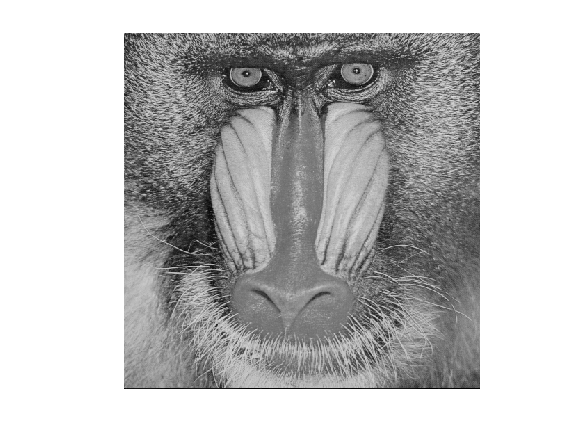

im = imread("/MATLAB Drive/images/mandrill.tif");
imshow(im)

## Implementation:

5x5 Kuwahara filter that uses four 3x3 quandrants as subregions

function out = kf(im)
    [rows, cols] = size(im);
    out = zeros(rows, cols);

    double_im = im2double(im);
    % Pad im with mirrored pixels on all sides extending by 2
    pim = padarray(double_im, [2 2], 'symmetric');

    for i = 3:rows+2
        for j = 3:cols+2

            % 5x5 region surrounding the current pixel
            r = pim(i-2:i+2,j-2:j+2);

            % Four overlapping 3x3 subregions
            sub1 = r(1:3,1:3);
            sub2 = r(1:3,3:5);
            sub3 = r(3:5,1:3);
            sub4 = r(3:5,3:5);

            means = [mean(sub1(:)), mean(sub2(:)), mean(sub3(:)), mean(sub4(:))];
            variances = [var(sub1(:),1) var(sub2(:),1), var(sub3(:),1), var(sub4(:),1)];
            [~, idx] = min(variances);

            out(i-2, j-2) = means(idx);
        end
    end
end

Using this on the input, we can demonstrate the effect of a 5x5 Kuwahara filter:

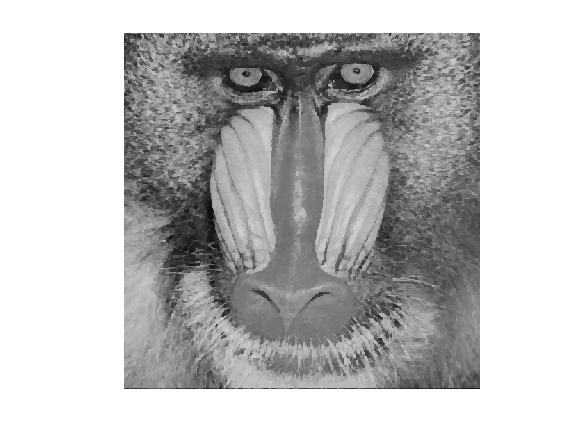

imkf = kf(im);
imshow(imkf)

Zooming in allows the effects to be much more apparent:

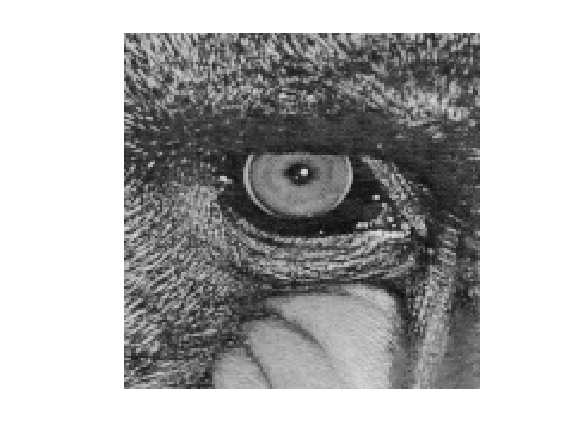

imzoom = im(1:149,103:251);
imzoomkf = imkf(1:149,103:251);
imshow(imzoom)

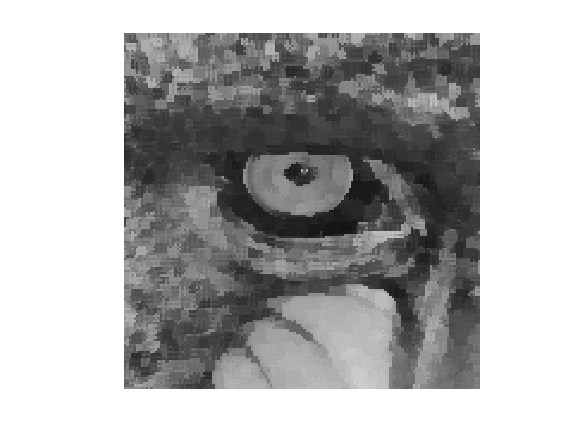

imshow(imzoomkf)